# 基于二阶系统的PID最优参数选择（23.12.3 卢羲）

## Part1 设计PID参数的一种思路

#### 1.1 PID会为原开环传递函数引入两个零点和一个零极点

- 若$K_d =1$，则PID传递函数为$\frac{s^2 +K_p s+K_i }{s}$，由韦达定理$K_p$是两个零点中心的两倍。若使$K_i =\frac{K_p^2 }{4}$，则恰好凑成完全平方式，两个零点重合，且都为$\frac{K_p }{2}$。

- 在此基础上将$K_i$加上$x^2$表明两个零点向上下分别移动$x$、减去$x^2$表明向左右分别移动$x$。

#### 1.2 只需设计（中心零点、微调方向、微调大小） 即可得到一个PID控制器参数

- 因此设计PID参数时可以假定$K_d =1$，随后选取一个$K_p$，让$K_i =\frac{K_p^2 }{4}$，

- 随后让$K_i +x^2$观察效果、$K_i -x^2$观察效果，通过上下左右移动的效果微调$K_i$。

#### 1.3 为保证基准一致，需将设计后的参数整体除以Kp，即将Kp归一化

s = tf("s");
G = 3/(s^2 -29.4);

% 中心为5
kd = 1;     kp = 10;      ki = kp^2/4;
p = [kp, ki, kd]./kp

p =     1.0000    2.5000    0.1000


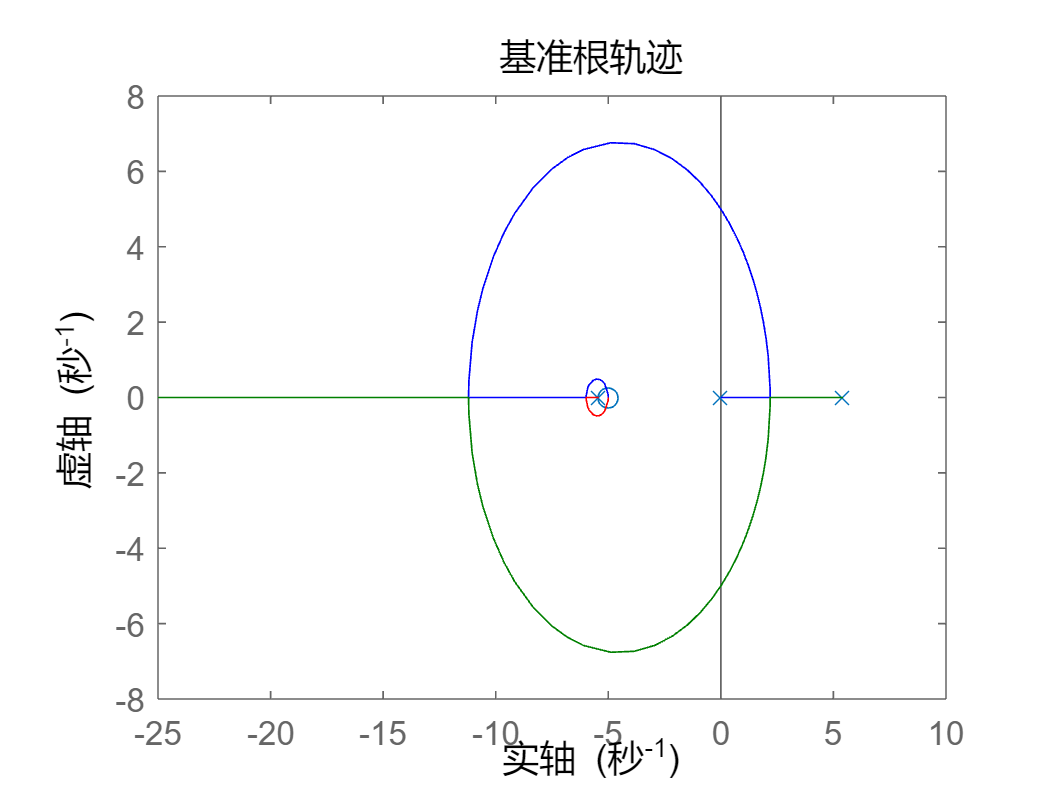

Gpid = (kd*s+kp+ki/s)/kp;      C_o = G*Gpid;
figure
rlocus(C_o)
title("基准根轨迹")


% 中心为5，上下移动2
kd = 1;     kp = 10;      ki = kp^2/4+4;
p = [kp, ki, kd]./kp

p =     1.0000    2.9000    0.1000


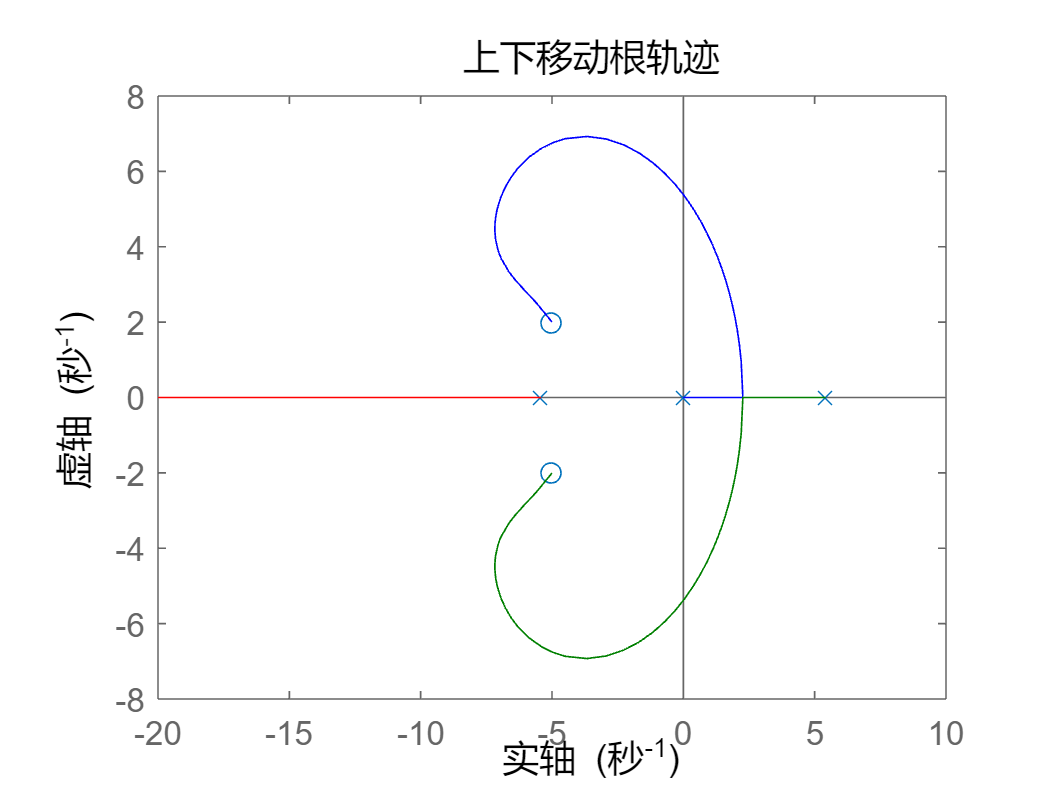

Gpid = (kd*s+kp+ki/s)/kp;      C_ud = G*Gpid;
figure
rlocus(C_ud)
title("上下移动根轨迹")


% 中心为5，左右移动2
kd = 1;     kp = 10;      ki = kp^2/4-4;
p = [kp, ki, kd]./kp

p =     1.0000    2.1000    0.1000


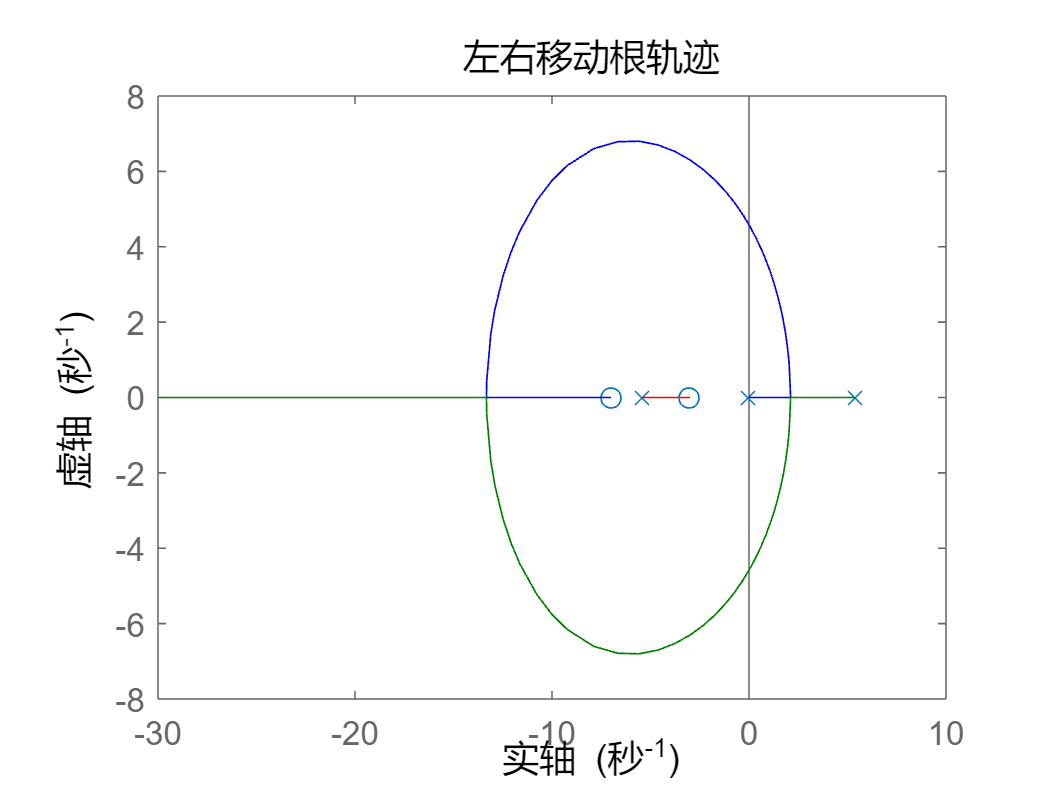

Gpid = (kd*s+kp+ki/s)/kp;      C_lr = G*Gpid;
figure
rlocus(C_lr)
title("左右移动根轨迹")

## Part2 以PD为引寻找最优参数

#### 2.1 超调来源于不同e分量的相交

- 闭环传递函数的零点为开环传递函数的零点、闭环传递函数的极点为各支根轨迹上根轨迹增益相同值的点。

- 系统的时域阶跃响应即对闭环传递函数除以$s$后求逆变换的结果。因此其除去常数分量外，其余都为$e$指数分量，且各分量的指数系数对应闭环传递函数的极点，即根轨迹上的点。各分量的权重由该分量对应的极点到其余零极点间的距离决定，这个参数较难确定。

- 对于一般的两极点闭环传递函数，响应分为两种情况：第一种情况是系数靠近虚轴的极点权重远大于远离虚轴的，响应表现为两分量负加权和，被靠近虚轴的极点主导。如以下情况一。

- 第二种情况靠近虚轴的极点权重同远离虚轴的极点相近或较小，此时响应表现右分量减去左分量，在开始左分量由于权重大成为主导，后续渐渐被右分量超越，两分量导数存在交点从而产生超调。如以下情况二。

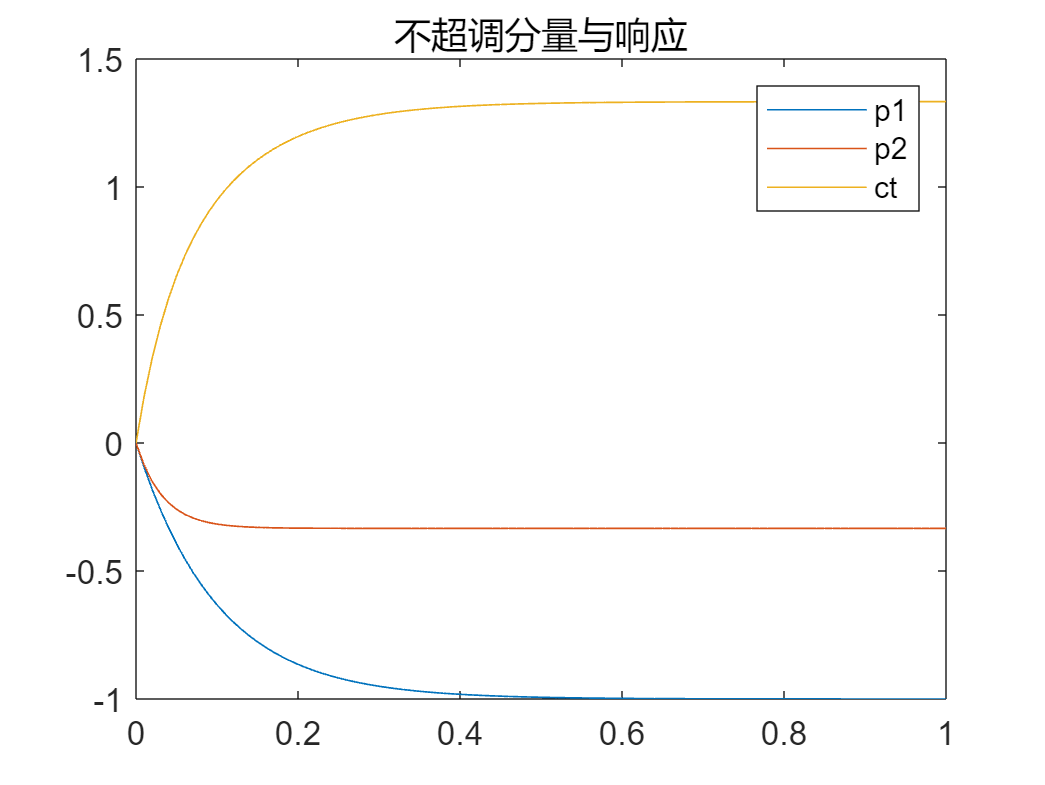

% 假若响应有两个分量exp(-10*t), -1/3*exp(-30*t)，则两分量和响应如下
t = 0:0.01:1;
p1 = exp(-10*t)-1;   p2 = exp(-30*t)./3-1/3;    ct = -p1 -p2;

figure
plot(t, p1)
hold on
plot(t, p2)
hold on
plot(t, ct)

legend("p1", "p2", "ct")
title("不超调分量与响应")

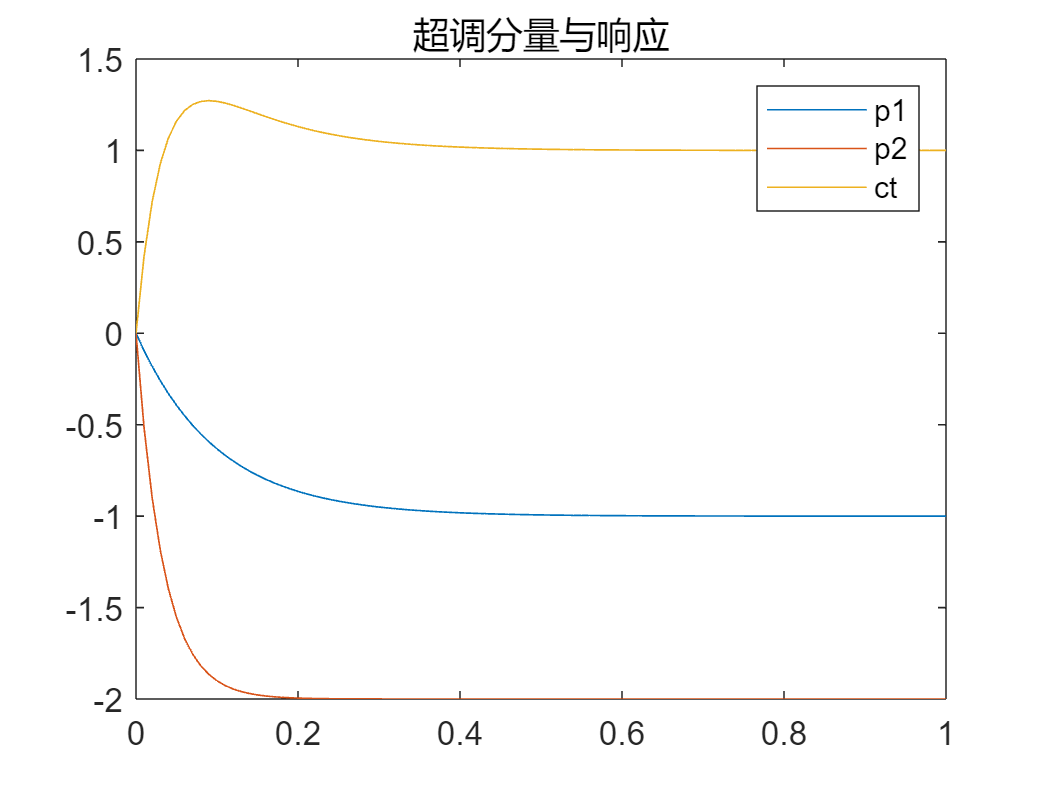



% 假若响应有两个分量exp(-t), -2*exp(-3t)，则两分量和响应如下
p1 = exp(-10*t)-1;   p2 = exp(-30*t).*2-2;      ct = p1 - p2;

figure
plot(t, p1)
hold on
plot(t, p2)
hold on
plot(t, ct)

legend("p1", "p2", "ct")
title("超调分量与响应")

#### 2.2 减少分量避免相交寻找最优Kd

- PD是PID的特例，固定$K_d =1$后，$K_p$值的相反数即为引入的零点，对于倒立摆系统而言，存在一个左侧极点，若用KD引入的零点将此极点消去，会直接减少一个响应分量，让分配给两个分量的权重分配给了一个分量，避免了一部分权重在两个分量变更主导权时的损失，同时也避免了超调或欠调，从而在理论上有更好的效果。

- 同时，若不消去此极点，随着根轨迹增益变大，总有一部分闭环极点停留在靠近虚轴的位置，也会减慢响应的速度，对快速性有不利影响。

- 综上，KD控制器设计中使$K_p$等于系统最靠近虚轴的负极点的值能得到最好的控制效果。（不消去正极点是由于无法完全消去，即使留下很小的差值，在正指数的作用下，该分量仍会在一段时间后发散，无法保证系统的稳定性）

% 以下展示不同Kp取值的根轨迹情况
kd = 1;     kp = 3;      ki = 0;
p = [kp, ki, kd]./kp

p =     1.0000         0    0.3333


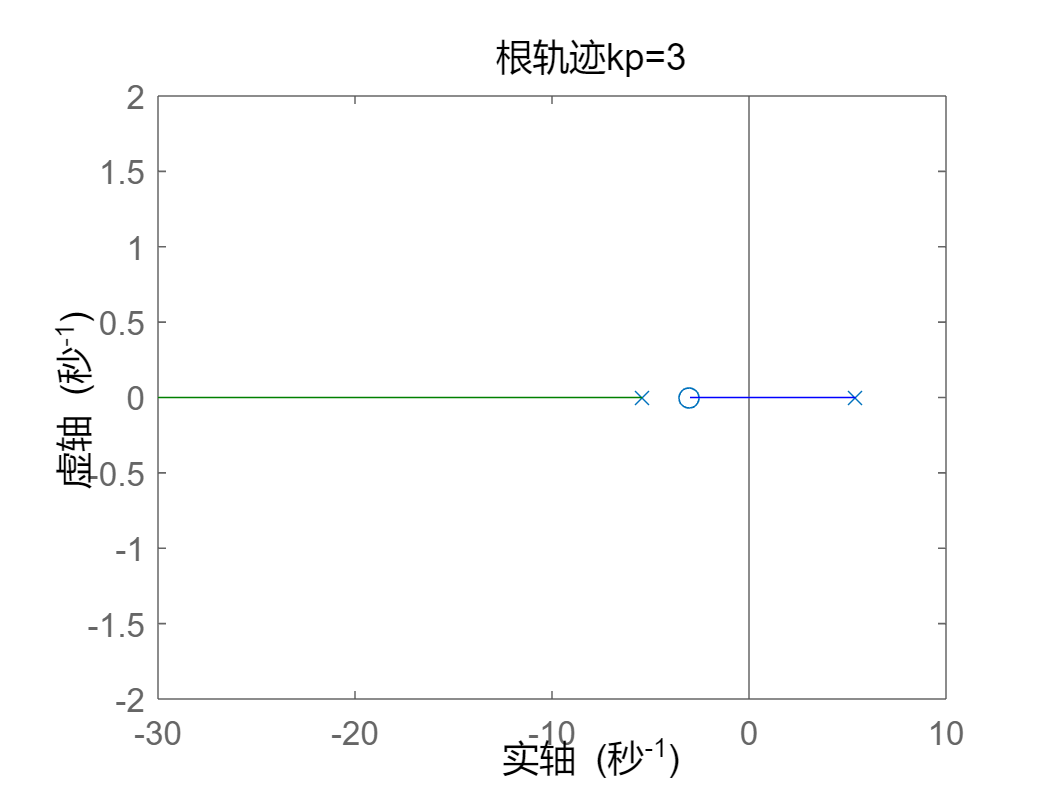

Gpid = (kd*s+kp+ki/s);      C_P1 = G*Gpid;
figure
rlocus(C_P1)
title("根轨迹kp=3")


kd = 1;     kp = sqrt(29.4);      ki = 0;
p = [kp, ki, kd]./kp

p =     1.0000         0    0.1844


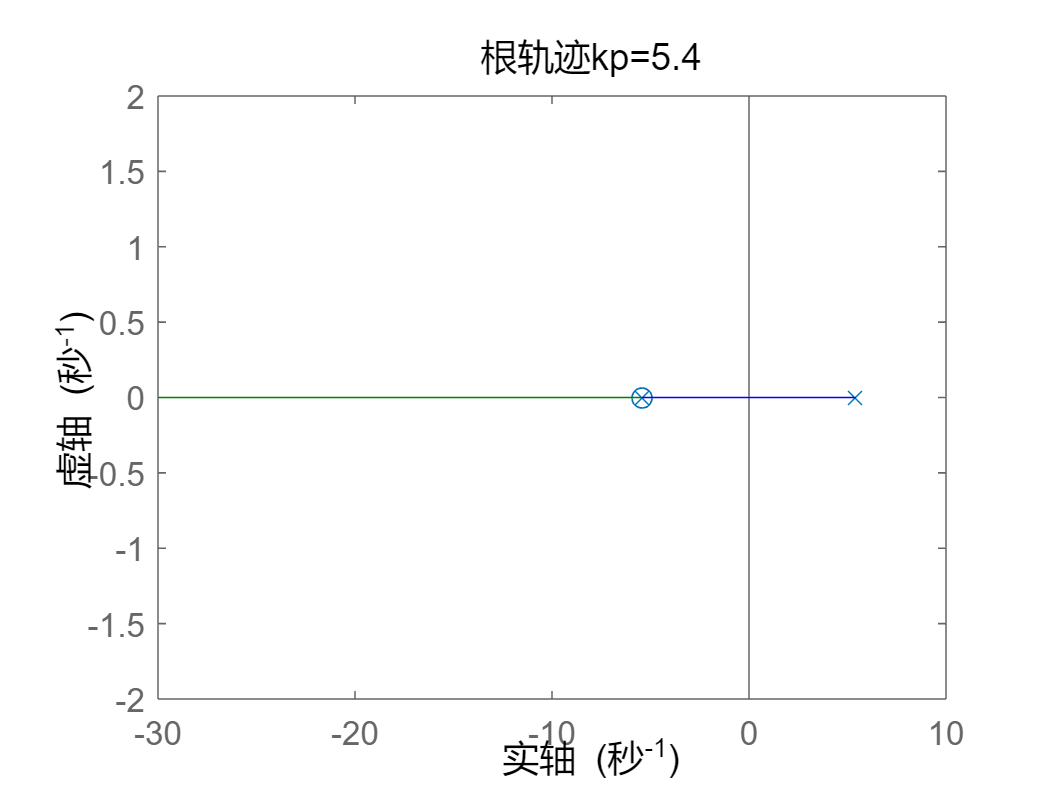

Gpid = (kd*s+kp+ki/s);      C_P2 = G*Gpid;
figure
rlocus(C_P2)
title("根轨迹kp=5.4")


kd = 1;     kp = 8;      ki = 0;
p = [kp, ki, kd]./kp

p =     1.0000         0    0.1250


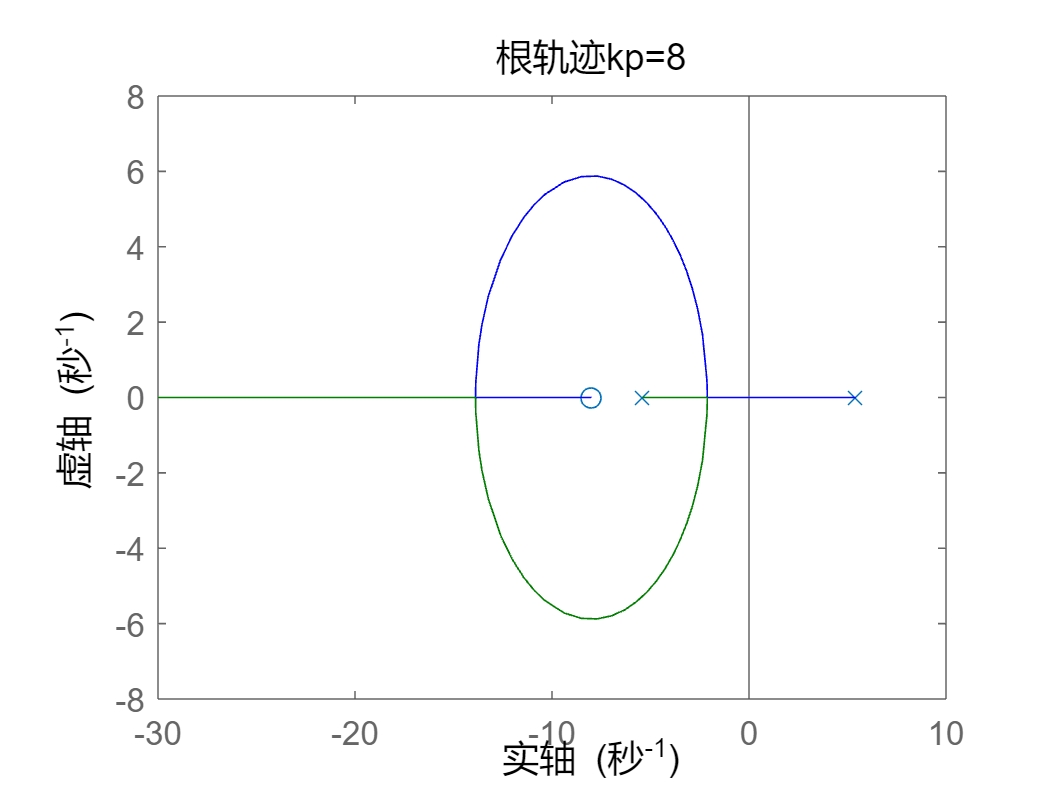

Gpid = (kd*s+kp+ki/s);      C_P3 = G*Gpid;
figure
rlocus(C_P3)
title("根轨迹kp=8")

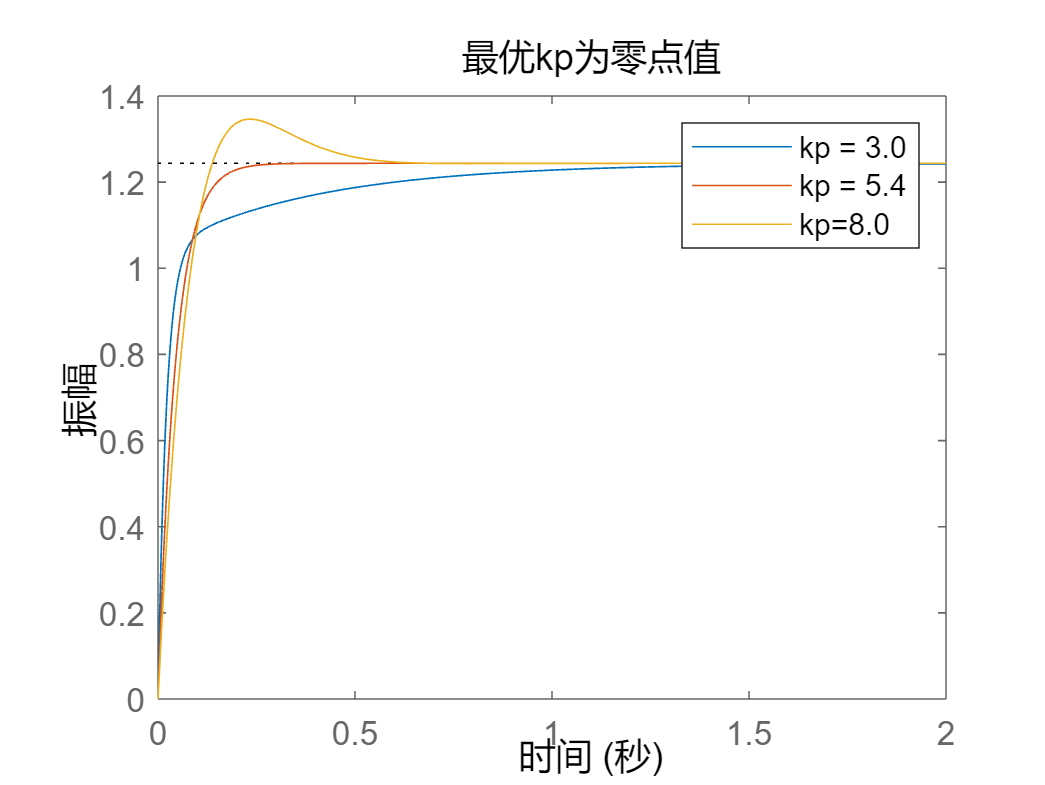

% 以下展示不同Kp取值的响应情况
k_root = 50;             % 根轨迹增益

kd = 1;     kp = 3;      ki = 0;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid; 
C_close1 = feedback(k_root*C, 1);
figure
step(C_close1, 2)

kd = 1;     kp = sqrt(29.4);      ki = 0;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close2 = feedback(k_root*C, 1);
hold on
step(C_close2, 2)

kd = 1;     kp = 8;      ki = 0;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close3 = feedback(k_root*C, 1);
hold on
step(C_close3, 2)

legend("kp = 3.0", "kp = 5.4", "kp=8.0")
title("最优kp为零点值")

#### 2.3 PD可以看作两个引入零点分别为0和Kp的分散PID

## Part3 基于微调确定最优PID参数

#### 3.1 从PD到PID，得到一个基础参数模板

- PD调节虽然快且稳，但存在很大的稳态误差，即使根轨迹增益调大也无法完全消除。不过既然由上部分推得PD控制时使$K_p$为靠虚轴负零点时效果最好，我们可以以此为基础，通过左右微调的方式寻找能否有更好的参数。

- 事实上，由第一部分可知：此时增大$K_i$的值即让PD控制中分散的两个零点向中间聚拢，在响应上呈现的效果是超调和上升时间基本不变，但在上升到峰值后开始下降，最终趋于1，整体上看似超调增大，但只是由于稳态误差的大大优化产生的谬误，本质上性能在各个方面都有所提升。

- 继续增大$K_i$的值，零点开始向上下移动，引入的正余弦分量增多，系统开始震荡。具体变化情况如下。

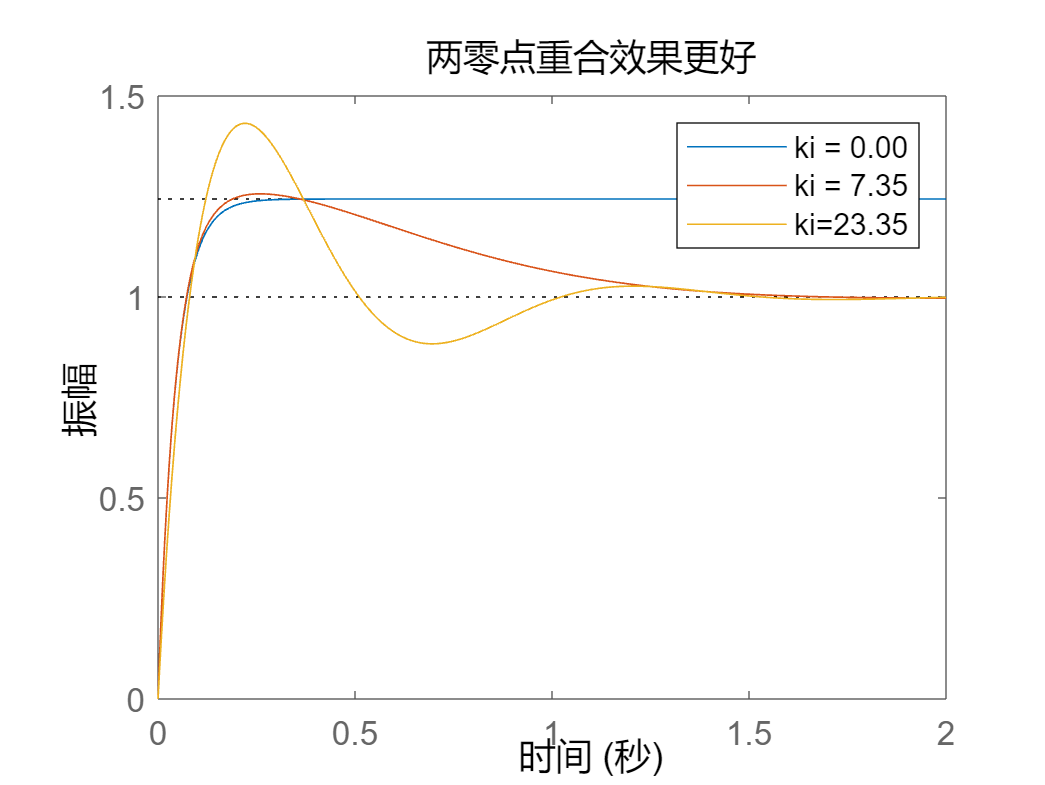

k_root = 50;             % 根轨迹增益

% 零点分散在左右
kd = 1;     kp = sqrt(29.4);      ki = 0;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid; 
C_close1 = feedback(k_root*C, 1);
figure
step(C_close1, 2)

% 零点重合
kd = 1;     kp = sqrt(29.4);      ki = kp^2/4;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close2 = feedback(k_root*C, 1);
hold on
step(C_close2, 2)

% 零点分散在上下
kd = 1;     kp = 8;      ki = kp^2/4+16;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close3 = feedback(k_root*C, 1);
hold on
step(C_close3, 2)

legend("ki = 0.00", "ki = 7.35", "ki=23.35");
title("两零点重合效果更好")

#### 3.2 微调对系统性能的影响，确定最优参数比例

- 以上结果显示，上下微调零点能引入正余弦分量加快响应速度，但同时会引入超调和震荡。事实情况中误差小于一定值时即可忽略，因此可略微让零点有一定的虚数分量，对响应的快速性更好。事实上，上下调整量越大对响应快速性的益处就越小，带来的震荡越多，因此即使希望得到更快速的效果，也不应应用这种微调方式。

- 向中心左右微调零点无法得到任何益处，故而不做考虑。

- 除了以上两种微调方式外，还可以左右微调零点中心，这种方式如果综合考虑快准稳三个方面，以超调面积作为指标来看并不如直接将重心按2.2方法配置效果好。但是，向右移动中心在增加震荡的情况下可以稳定加快响应速度，因此迫切需要低根轨迹增益下的快速响应性能时可通过这种方式调节。值得一提的是根轨迹增益越大，这种方式得到的综合性能差距2.2方式越差，因此斟酌使用。

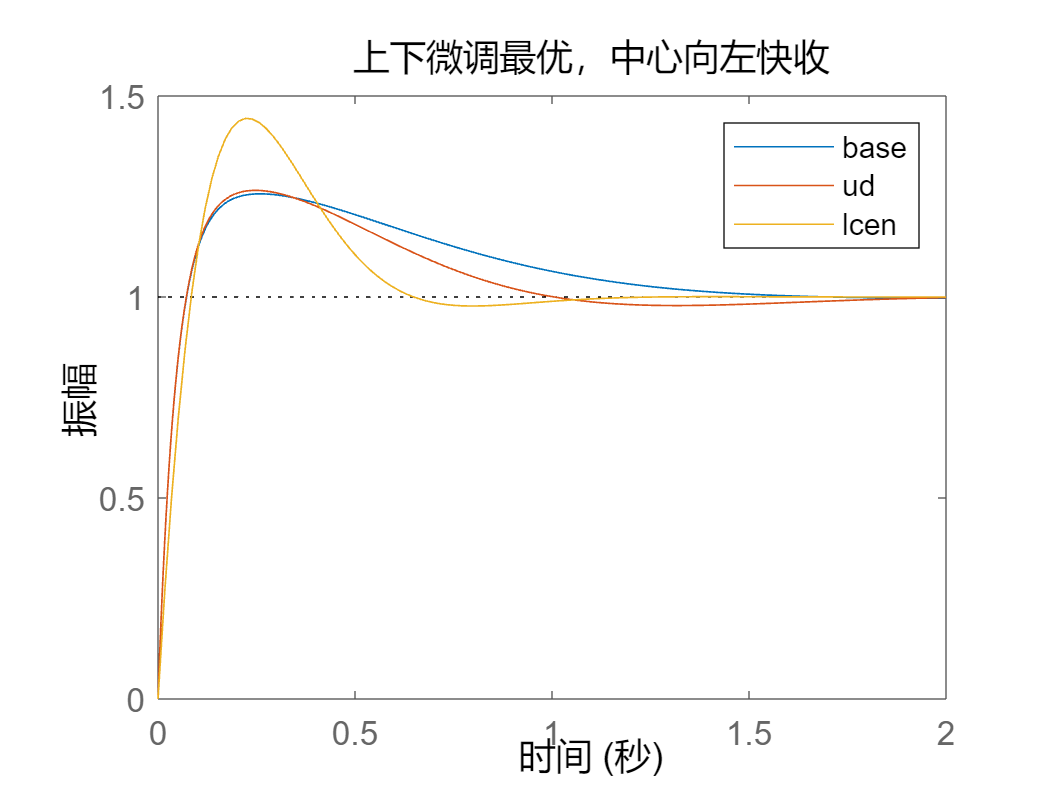

k_root = 50;             % 根轨迹增益

% 基准
kd = 1;     kp = sqrt(29.4);      ki = kp^2/4;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid; 
C_close1 = feedback(k_root*C, 1);
figure
step(C_close1, 2)

% 上下微调
kd = 1;     kp = sqrt(29.4);      ki = kp^2/4+4;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close2 = feedback(k_root*C, 1);
hold on
step(C_close2, 2)

% 中心向左
kd = 1;     kp = 8+1;      ki = kp^2/4;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close3 = feedback(k_root*C, 1);
hold on
step(C_close3, 2)

legend("base", "ud", "lcen")
title("上下微调最优，中心向左快收")

#### 3.3 最优PID参数选取规则

####     `了解系统参数时：`

- 确定模板：$K_d =1$、$K_p$取最靠近虚轴的负极点、$K_i =\frac{K_p^2 }{4}$，随后同除以$K_p$。

- 选择合适的根轨迹增益直到响应达到较好的效果。

- 若需求是寻找综合最优的参数，则略微增大$K_i$，尝试若干次后挑选最满意的结果；若需求是只考虑快稳不考虑稳态误差，则将模板值的$K_i$。

- 若需求是在当前根轨迹增益下尽可能寻找快速性最好而对稳定性要求不严格的情况下，则不断减小$K_d$，同时保证$K_i =\frac{K_p }{4K_d }$（即两零点重合），直到第一向下调节至比一小时，再略微增大$K_i$即可得到最好的效果。

####     `不了解系统参数时：`

- 确定模板：只增大$K_p$，其余参数置零，直到得到一个较为满意的响应曲线；一般情况下该曲线存在超调，此时慢慢增大$K_d$直到恰好消除超调，则得到了系统的一个负极点$\frac{K_P }{K_d }$。

- 该极点不一定是最靠近虚轴的，可以继续增大$K_d$寻找最优极点，也可以按照了解参数时的方法完成后续参数选取

k_root = 500;             % 根轨迹增益

% 综合最优
kd = 1;     kp = sqrt(29.4);      ki = kp^2/4+36;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid; 
C_close1 = feedback(k_root*C, 1);
figure
step(C_close1, 0.5)
p.*500

ans = 1.0e+03 *

    0.5000    3.9975    0.0922



% 响应最快
kd = 1;     kp = sqrt(29.4)*3;      ki = kp^2/4+25;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close2 = feedback(k_root*C, 1);
hold on
step(C_close2, 0.5)
p.*500

ans = 1.0e+03 *

    0.5000    2.8018    0.0307



% 不管误差
kd = 1;     kp = sqrt(29.4);      ki = 0;
p = [kp, ki, kd]./kp;
Gpid = (kd*s+kp+ki/s)/kp;      C = G*Gpid;
C_close3 = feedback(k_root*C, 1);
hold on
step(C_close3, 0.5)
p.*500

ans =   500.0000         0   92.2139


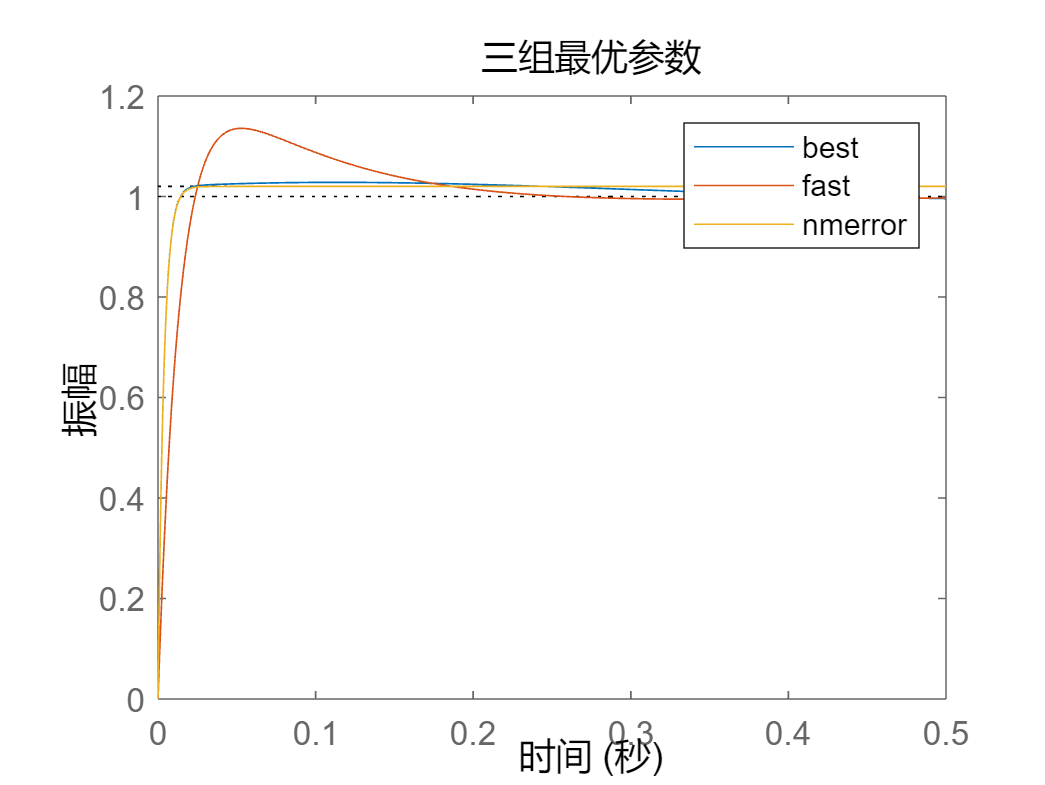


legend("best", "fast", "nmerror")
title("三组最优参数")